load ('CNC110X69-5.mat');
load ('Samsung_30Q_18650_pack.mat');

addpath("Functions/");
addpath("Simulink/");
addpath("Bode/");

% Step input settings:
stepp.sim_time = 20 * 10^-3; % [ms]
stepp.step_time = 2 * 10^-3; % [ms]
% stepp.ir01 = 0.1;
% stepp.ir02 = pv_data.Impp;
stepp.ir01 = 0.1;
stepp.ir02 = 0.05;

% Switching frequency:
boost.f = 1 * 10^5; % [Hz]
boost.T = 1/boost.f;

% Maximum duty cycle that can be achieved:
boost.D_max = 1 - pv_data.Vmpp/Bat.Ubat_nom; % MPP mode of operation

% Passive elements:
% boost.R = 50;
boost.Rt = 1*10^5;
boost.RL = 10 * 10^-3;
boost.Ru = Bat.Ru;
boost.L = 80 * 10^-6;
boost.Cu = 100 * 10^-6;
boost.Ci = 100 * 10^-6;
boost.Cbat = Bat.Qbat_tot/(Bat.Ubat_charged - Bat.Ubat_cut_off);

% Lomna frekv. izlaznog RC kruga:
% f_RC = 1/(2*pi*boost.R*boost.Ci)

## PV resistance:

pv_in.G = 1000;     %[W/m^2]
pv_in.t = 25;       %[deg]
pv_in.ramp = 1;     %[/]

pv = calc_pv_res("Solar", pv_in);


clear pv_in;

## Steady state operating point parameters:

% CCM mode parameters:
ccm_op = ccm_param(boost, Bat, pv_data);
% CCM mode with compensation ramp parameters:
ccm_m_op = ccm_m_param(boost, Bat, pv_data);
Upv0 = ccm_m_op.Upv0

Upv0 = 5

Ipv0 = ccm_m_op.Ipv0

Ipv0 = 0.2500

Ir0 = ccm_m_op.Ir0

Ir0 = 0.2500

Ubat0 = ccm_m_op.Ubat0

Ubat0 = 7.2000

Im0 = ccm_m_op.Im0

Im0 = -0.0441

m0 = ccm_m_op.m0

m0 = 3.3750e+04

ro = ccm_m_op.ro

ro = -0.5779

L_lim = ccm_m_op.L_lim

L_lim = 3.1088e-04

% DCM mode parameters:
dcm_op = dcm_param(boost, Bat, pv_data);
Upv0 = dcm_op.Upv0

Upv0 = 5

Ipv0 = dcm_op.Ipv0

Ipv0 = 0.2500

Ir0 = dcm_op.Ir0

Ir0 = 0.2500

Ubat0 = dcm_op.Ubat0

Ubat0 = 8.4000

m0 = dcm_op.m0

m0 = 3.3750e+04

ro = dcm_op.ro

ro = 0.4167


sim_op = dcm_op;

clear Upv0 Ipv0 Ir0 Ubat0 Im0 m0 ro L_lim

## Colors:

% 0, 0, 0;                    % black
% 0, 0, 1;                    % blue
% 1, 0, 0;                    % red
% 0, 1, 0;                    % green
% 0.9290, 0.6940, 0.1250;     % yellow-gold
% 0.8500, 0.3250, 0.0980;     % reddish-orange

myColors = [
    0, 0, 0;                    % black
    0, 0, 1;                    % blue
    1, 0, 0;                    % red
    0, 1, 0;                    % green
];

## CCM, CV tf's:

[ccm_sys, ccm_separate_tfs] = ccm_calc_tfs(boost, ccm_op);

plot_data.t = linspace(0, 0.2*10^-3,1000);
plot_data.labels = {"Full sys", "PT2 with zero", "PT2 aprox", "PT1 aprox"};
plot_data.colors = myColors;
plot_data.y_label = "U_b_a_t [mV]";

% Refrence current:
plot_data.fgtitle = "U_b_a_t response to I_r, CCM-CV";

Ir.full = ccm_separate_tfs.G_Ubat_Ir_full;
Ir.normal = ccm_separate_tfs.G_Ubat_Ir;
Ir.nozero = ccm_separate_tfs.G_Ubat_Ir_nozero;
Ir.red = ccm_separate_tfs.G_Ubat_Ir_red;

ccm_separate_tfs.G_Ubat_Ir

plot_step_responses(Ir, plot_data);

% Input voltage:
plot_data.fgtitle = "U_b_a_t response to U_p_v, CCM-CV";

Upv.full = ccm_separate_tfs.G_Ubat_Upv_full;
Upv.normal = ccm_separate_tfs.G_Ubat_Upv;
Upv.nozero = ccm_separate_tfs.G_Ubat_Upv_nozero;
Upv.red = ccm_separate_tfs.G_Ubat_Upv_red;

plot_step_responses(Upv, plot_data);

clear Ir Upv plot_data;

## CCM,CV (compensation ramp):

[ccm_m_sys, ccm_m_separate_tfs] = ccm_m_calc_tfs(boost, ccm_m_op);

plot_data.t = linspace(0, 0.2*10^-3,1000);
plot_data.labels = {"Full sys", "PT1 aprox"};
plot_data.colors = myColors;
plot_data.linestyles = {'-','--'};
plot_data.y_label = "U_b_a_t [mV]";

% Refrence current:
plot_data.fgtitle = "U_b_a_t response to I_r, CCM-CV";

Ir.full = ccm_m_separate_tfs.G_Ubat_Ir_full;
Ir.red = ccm_m_separate_tfs.G_Ubat_Ir;

ccm_m_separate_tfs.G_Ubat_Ir

ans =
 
      1.254e-08 s + 0.001686
  ------------------------------
  2.78e-12 s^2 + 1.095e-05 s + 1
 
Continuous-time transfer function.
Model Properties



Tp1 = ccm_m_sys.Tp1

Tp1 = 1.0694e-05

Tp2 = ccm_m_sys.Tp2

Tp2 = 2.5998e-07

Tz1 = ccm_m_sys.Tz1

Tz1 = 7.4350e-06

Tz2 = ccm_m_sys.Tz2

Tz2 = 7.1257e-06

Zeta = ccm_m_sys.zeta

Zeta = 3.2847

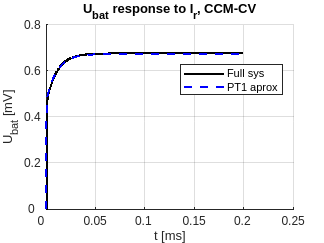


plot_step_responses(Ir, plot_data);


% Input voltage:
plot_data.fgtitle = "U_b_a_t response to U_p_v, CCM-CV";

Upv.full = ccm_m_separate_tfs.G_Ubat_Upv_full;
Upv.red = ccm_m_separate_tfs.G_Ubat_Upv;

ccm_m_separate_tfs.G_Ubat_Upv

ans =
 
     1.048e-09 s + 0.0001471
  ------------------------------
  2.78e-12 s^2 + 1.095e-05 s + 1
 
Continuous-time transfer function.
Model Properties


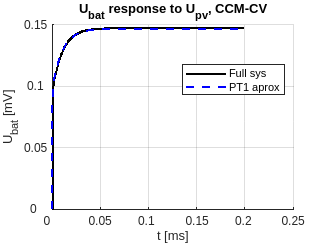


plot_step_responses(Upv, plot_data);


clear Tp1 Tp2 Tz1 Tz2 Zeta;
clear plot_data;

## DCM, CV

[dcm_sys, dcm_separate_tfs] = dcm_calc_tfs(boost, dcm_op);

dcm_separate_tfs.G_Ubat_Ir_full

ans =
 
       4.097e05 s + 2.48e04
  ------------------------------
  165.2 s^2 + 6.353e08 s + 912.9
 
Continuous-time transfer function.
Model Properties


dcm_separate_tfs.G_Ubat_Ir;

dcm_separate_tfs.G_Ubat_Upv_full

ans =
 
        2.225e04 s + 1347
  ------------------------------
  165.2 s^2 + 6.353e08 s + 912.9
 
Continuous-time transfer function.
Model Properties


dcm_separate_tfs.G_Ubat_Upv;

dcm_sys.K1

ans = 6.4487e-04

dcm_sys.K2

ans = 3.5015e-05

## Full system:

% CCM-CV:
[G_sys_ccm, sys_ccm_param] = sys_ccm(ccm_m_sys, ccm_m_op, boost);

G_sys_ccm

G_sys_ccm =
 
      3.397e-06 s + 0.003386
  ------------------------------
  2.139e-08 s^2 + 0.002011 s + 1
 
Continuous-time transfer function.
Model Properties



% DCM-CV:
[G_sys_dcm, sys_dcm_param] = sys_dcm(dcm_sys, dcm_op, boost);

G_sys_dcm

G_sys_dcm =
 
   1.29e-06 s + 0.0003531
  -------------------------
  5.2e-10 s^2 + 0.002 s + 1
 
Continuous-time transfer function.
Model Properties



clear plot_data;

## linear vs nonlinear:

sim_op = dcm_op;

lin = sim("Simulink/Strujni_nacin_v2.slx");

nonlin = sim("Nealinearni_realni_v2.slx");

IL_nonlin = nonlin.get("IL").Data;
Ubat_nonlin = nonlin.get("Ubat").Data;
% Ubat_nonlin = movmean(Ubat_nonlin, 300);
Ubat_lin = lin.get("Ubat").Data;
t = lin.get("Ubat").Time * 1000;

fig = figure;

% % Set paper properties on the figure
% fig.PaperUnits = 'centimeters';
% fig.PaperSize = [21 29.7];           % width x height in inches
% fig.PaperPosition = [0 0 8 4.5];   % position on paper (fill whole paper)

% for 11 x 9 (W x H)
width_px = round(11/2.54 * 300); % ~1335 pixels
height_px = round(9/2.54 * 300); % ~1146 pixels

fig = figure('Units','pixels', 'Position', [100 100 width_px height_px]); % W x H

% Plotting a 3 x 1 array of graphs:
layout = tiledlayout(3,1);
layout.TileSpacing = 'compact';
layout.Padding = 'compact';

% Output voltage:
nexttile;
hold on;
plot(t, Ubat_nonlin, 'b', 'LineWidth', 1.5);
plot(t, Ubat_lin, '--r', 'LineWidth', 2.5);
hold off;
xlabel("\it{t}\rm [ms]");
yl = ylabel("\it{U_{bat}}\rm [V]")

yl =   Text (\it{U_{bat}}\rm [V]) with properties:

                 String: '\it{U_{bat}}\rm [V]'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [-0.8528 8.4002 -1]
                  Units: 'data'

  Show all properties


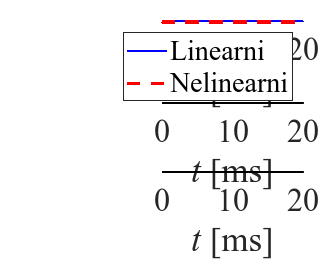

% yl.Position(1) = -1;
legend("Linearni", "Nelinearni");
axis auto;
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Error:
nexttile;
error = (Ubat_nonlin - Ubat_lin)*1000;
plot(t, error, 'k', 'LineWidth', 1.5);
yl = ylabel("\it{Pogreška}\rm [mV]");
% yl.Position(1) = -1;
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

% Struja zavojnice:
nexttile;
plot(t, IL_nonlin, 'k', 'LineWidth', 1.5);
yl = ylabel("\it{i_L}\rm [A]");
% yl.Position(1) = -1;
xlabel("\it{t}\rm [ms]");
ax = gca;
ax.FontSize = 24;
ax.FontName = 'Times New Roman';
grid on;

exportgraphics(gcf, 'graf_ccm_full.png', 'Resolution', 300);

## Pole and zero plot:

% for 11 x 9 (W x H)
width_px = round(15.52/2.54 * 300); % ~1335 pixels
height_px = round(7.5/2.54 * 300); % ~1146 pixels

z1 = zero(ccm_m_separate_tfs.G_Ubat_Ir);
z2 = zero(ccm_m_separate_tfs.G_Ubat_Upv);
p = pole(ccm_m_separate_tfs.G_Ubat_Upv);
p2 = p(1);
p1 = p(2);
clear p;

fig = figure('Units','pixels','Position',[100 100 width_px height_px]);

%% --- Compute text offset based on axis scale ---
ax = gca;
xrange = diff(ax.XLim);
yrange = diff(ax.YLim);

% dx = 0.05 * xrange;   % larger offset than before
% dy = 0.03 * yrange;

% Set default font for axes and text within this figure
set(fig, 'DefaultAxesFontName', 'Times New Roman', 'DefaultAxesFontSize', 24);
set(fig, 'DefaultTextFontName', 'Times New Roman', 'DefaultTextFontSize', 24);

hz1 = plot(real(z1), imag(z1), 'ro', 'MarkerSize', 15, 'LineWidth', 2); hold on;
% text(real(z1), imag(z1) + dy, 'T_{z1}', ...
%                 'Interpreter', 'tex', ...
%                 'HorizontalAlignment', 'right', ...
%                 'VerticalAlignment', 'bottom', ...
%                 'FontSize', 24);

hz2 = plot(real(z2), imag(z2), 'go', 'MarkerSize', 15, 'LineWidth', 2);
% text(real(z2), imag(z2) - dy, 'T_{z2}', ...
%                 'Interpreter', 'tex', ...
%                 'HorizontalAlignment', 'left', ...
%                 'VerticalAlignment', 'top', ...
%                 'FontSize', 24);

plot(real(p1), imag(p1), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p1), imag(p1), 'T_{p1}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

plot(real(p2), imag(p2), 'bx', 'MarkerSize', 15, 'LineWidth', 2);
text(real(p2), imag(p2), 'T_{p2}', ...
                'Interpreter', 'tex', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'bottom', ...
                'FontSize', 24);

grid on;
xlabel('$Realna$ $os$', 'Interpreter', 'latex');
ylabel('$Imaginarna$ $os$', 'Interpreter', 'latex');
title('$Polovi/Nule$', 'Interpreter', 'latex');

%% --- Legend (zeros only, color-linked) ---
legend([hz1, hz2], {'$T_{z1}$', '$T_{z2}$'}, ...
    'Interpreter', 'latex', ...
    'Location','northeast');

hold off;

exportgraphics(gcf, 'graf_ccm_pz.png', 'Resolution', 300);

## Bode plot:

unpackStruct(sys_ccm_param)
% cf (cutoff frequency):
wz = 1/Tz;
wp1 = 1/Tp1;
wp2 = 1/Tp2;

w = logspace(0, 6, 1000);

[mag_z, ph_z] = Zero_frq_reponse(w, wz);
[mag_p1, ph_p1] = Pole_frq_response(w, wp1);
[mag_p2, ph_p2] = Pole_frq_response(w, wp2);

mag_dB = 20*log10(K) + mag_z + mag_p1 + mag_p2;
phase_deg  = ph_z + ph_p1 + ph_p2;

figure();
bode(G_sys_ccm);
grid on;


t = tiledlayout(2, 1);
t.TileSpacing = 'compact';
t.Padding = 'compact';

nexttile
semilogx(w, mag_dB, 'LineWidth', 1.5);
xline(wz, '--r', 'wz', 'LineWidth', 1.2);
xline(wp1, '--r', 'wp1', 'LineWidth', 1.2);
xline(wp2, '--r', 'wp2', 'LineWidth', 1.2);
grid on;
% title('Magnitude plot');
% xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
set(gca, 'FontSize', 11);

nexttile
semilogx(w, phase_deg, 'LineWidth', 1.5);
grid on;
% title('Phase plot');
xlabel('Frequency (rad/s)');
ylabel('Phase (degrees)');
set(gca, 'FontSize', 11);